clear


d = 25.4 % Diámetro agujero mm

d = 25.4000

h = 6.35 % Grosor placa mm

h = 6.3500

l = 50 % Longitud vertical mm

l = 50

w = 40 % Ancho placa mm 

w = 40


Area =pi/4*d^2  *2

Area = 1.0134e+03


% https://www.elesa-ganter.es/es/esp/Juntas--Horquillas--DIN71752

## Fatiga

%SoporteBiela=readtable("MatLab cinetica\Reacciones biela\A3-soporte-biela.txt","Delimiter"," ");
%SoporteBiela=readtable("MatLab cinetica\Reacciones biela\B3-soporte-biela.txt","Delimiter"," ");
SoporteBiela=readtable("MatLab cinetica\Reacciones soporte\C3-soporte-biela.txt","Delimiter"," ");


SoporteBiela.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M"];

vectorTiempo=SoporteBiela.T;

SoporteBielaFx=SoporteBiela.Fy;
SoporteBielaFy=SoporteBiela.Fz;
SoporteBielaFz=SoporteBiela.Fx;

max(abs(SoporteBielaFx))

ans = 6.4128e+03

max(abs(SoporteBielaFy))

ans = 0.8904

max(abs(SoporteBielaFz))

ans = 0.0710


max(SoporteBiela.F)

ans = 6.4128e+03


Sut = 630 % MPa -> 100 ksi 

Sut = 630

Sy = 530 % MPa

Sy = 530



tau=SoporteBielaFx/Area

tau =    -4.4862
   -4.7260
   -4.9650
   -5.2024
   -5.4374
   -5.6692
   -5.8960
   -6.1203
   -6.3279
   -6.2908


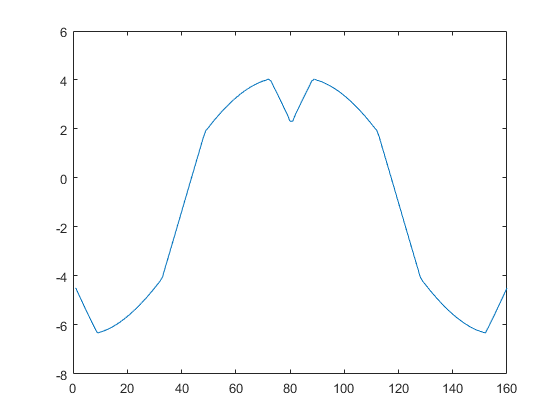



plot(tau)


sigma=sqrt(3)*tau

sigma =    -7.7703
   -8.1856
   -8.5996
   -9.0109
   -9.4179
   -9.8194
  -10.2122
  -10.6006
  -10.9602
  -10.8960


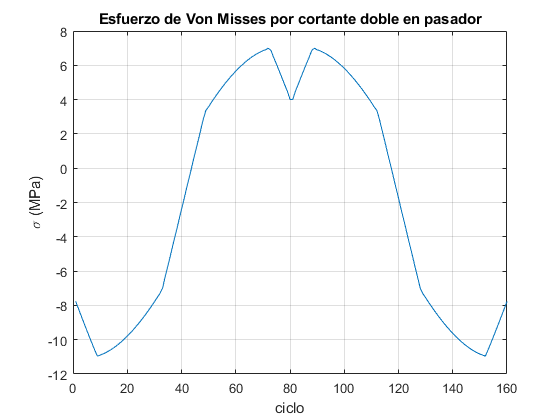

plot(sigma)
xlabel("ciclo")
ylabel("\sigma (MPa)")
title("Esfuerzo de Von Misses por cortante doble en pasador")
grid on



Fcar = 1 % Carga, carga axial

Fcar = 1


Ftam=1.189*(d)^(-0.097)

Ftam = 0.8688

%Ftam = 1.189 * (d) ^ (-0.097) % Tamaño, 8 mm < d <= 250 mm

Fsup = 4.51 * (Sut) ^ (-0.265) % Superficie, rolado en frío

Fsup = 0.8172

Ftem = 1 % Temperatura, T <= 450 °C

Ftem = 1

Fcon = 0.814 % Confiabilidad, 99%

Fcon = 0.8140

SeSC = 0.5*Sut

SeSC = 315

Se = SeSC * Fsup * Fcar * Ftem * Ftam * Fcon

Se = 182.0536


Sigma_Alternante=abs(0.5*(max(sigma)-min(sigma)))

Sigma_Alternante = 8.9789

Sigma_Medio=abs(0.5*(max(sigma)+min(sigma)))

Sigma_Medio = 1.9813

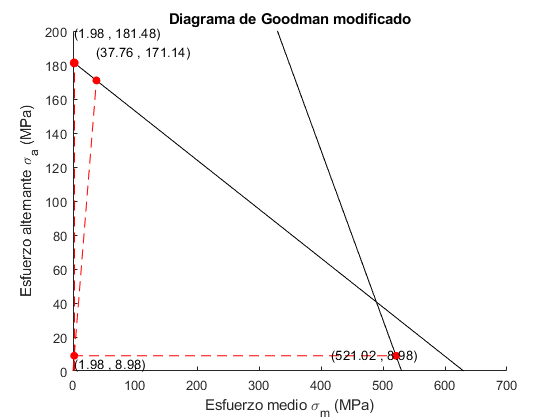

FS1 = 20.2120

FS2 = 19.0604

FS3 = 262.9681

FactorMinimo = 19.0604



FactorMinimo = diagramaGoodman(Sigma_Alternante,Sigma_Medio,Sut,Sy,Se,true)

function FSMin=diagramaGoodman(EsigmaA,EsigmaM,ESut,ESy,ESe,tension)
syms x1 x2 x3 x4 x5

if(tension)
sigmaA=EsigmaA;
sigmaM=EsigmaM;
Sut=ESut;
Sy=ESy;
Se=ESe;
lineaF=@(x)    Sy-x;
goodManM=@(x)  Se-x.*Se./Sut;
lineaC=@(x)     sigmaA.*x./sigmaM;

Fr=sigmaA.*x1/sigmaM==Se-x1./Sut.*Se;
Fq= Sy-x2==sigmaA;
Fq2=Se-x5./Sut.*Se==sigmaA;

FSm=double(solve(Fr,x1));
FSy=double(solve(Fq,x2));
FSy2=double(solve(Fq2,x5));

if(FSy2<FSy)
    FSy=FSy2;
end




figure()
scatter(sigmaM,sigmaA,"r","filled")
hold on
fplot(lineaF,[0 Sy],"k")
fplot(goodManM,[0 Sut],"k")
fplot(lineaC,[0 FSm],"r--")
stem(sigmaM,goodManM(sigmaM),"r--","filled")
scatter(FSm,goodManM(FSm),"r","filled")
scatter(FSy,sigmaA,"r","filled")
fplot(sigmaA,[0 FSy],"r--")
scatter(sigmaM,sigmaA,"r","filled")
text(1.1*sigmaM,0.5*sigmaA,sprintf('(%.2f , %.2f)', sigmaM,sigmaA))
text(1.1*sigmaM,1.1*goodManM(sigmaM),sprintf('(%.2f , %.2f)', sigmaM,goodManM(sigmaM)))
text(FSm,1.1*goodManM(FSm),sprintf('(%.2f , %.2f)', FSm,goodManM(FSm)))
text(0.8*FSy,1.1*sigmaA,sprintf('(%.2f , %.2f)', FSy,sigmaA))
hold off
ylim([0 Se*1.1])
xlabel("Esfuerzo medio \sigma_m (MPa)")
ylabel("Esfuerzo alternante \sigma_a (MPa)")
title("Diagrama de Goodman modificado")
FS1=goodManM(sigmaM)/sigmaA
FS2=sqrt(FSm^2+goodManM(FSm)^2)/sqrt(sigmaM^2+sigmaA^2)
FS3=FSy/sigmaM
FSMin=min([FS1 FS2 FS3]);

else
    
    
sigmaA=EsigmaA;
sigmaM=-EsigmaM;
Sut=ESut;
Sy=ESy;
Se=ESe;
lineaF=@(x)    Sy+x;
goodManM=@(x)  Se;
lineaC=@(x)     sigmaA.*x./sigmaM;
Fr=sigmaA.*x1/sigmaM==Se;
Fq= Sy+x2==sigmaA;
Fc2=Se==Sy+x3;
FSm=double(solve(Fr,x1));
FSy=double(solve(Fq,x2));
FSn=double(solve(Fc2,x3));
figure()
scatter(sigmaM,sigmaA,"r","filled")
hold on
fplot(lineaF,[-Sy 0],"k")
fplot(goodManM,[FSn 0],"k")
fplot(lineaC,[FSm 0],"r--")
stem(sigmaM,goodManM(sigmaM),"r--","filled")
scatter(FSm,goodManM(FSm),"r","filled")
scatter(FSy,sigmaA,"r","filled")
fplot(sigmaA,[FSy 0],"r--")
scatter(sigmaM,sigmaA,"r","filled")
text(4*sigmaM,1.1*sigmaA,sprintf('(%.2f , %.2f)', sigmaM,sigmaA))
text(3*sigmaM,1.05*Se,sprintf('(%.2f , %.2f)', sigmaM,goodManM(sigmaM)))
text(1.5*FSm,0.95*Se,sprintf('(%.2f , %.2f)', FSm,goodManM(FSm)))
text(1.1*FSy,1.1*sigmaA,sprintf('(%.2f , %.2f)', FSy,sigmaA))
hold off
ylim([0 Se*1.2])
xlabel("Esfuerzo medio \sigma_m (MPa)")
ylabel("Esfuerzo alternante \sigma_a (MPa)")
title("Diagrama de Goodman modificado (Compresión)")
ax=gca;
ax.YAxisLocation = 'right';
FS1=Se/sigmaA
FS2=sqrt(FSm^2+Se^2)/sqrt(sigmaM^2+sigmaA^2)
FS3=FSy/sigmaM
FSMin=min([FS1 FS2 FS3]); 
end
end
